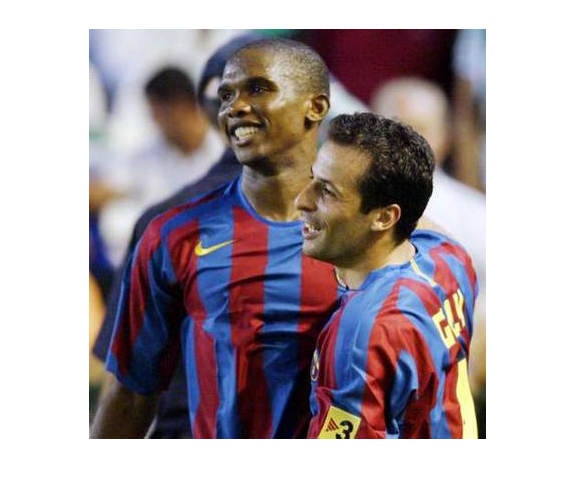

im = imread('probaB5.jpg');
im2 = imread('probaB1.jpg');
im3 = imread('probaB6.jpg');
im4 = imread('probaB6.jpg');

imshow(im);

tam = 75;
[RGModelHist, GBModelHist, BRModelHist, RGBModelHist] = getHists(im, tam);

ans = 404.0151

ans = 404.0151

c = uint16
152

f = uint16
322

[RGModelHist2, GBModelHist2, BRModelHist2, RGBModelHist2] = getHists(im2, tam);

ans = 315.1171

ans = 315.1171

c = uint16
156

f = uint16
217

[RGModelHist3, GBModelHist3, BRModelHist3, RGBModelHist3] = getHists(im3, tam);

ans = NaN

ans = NaN

c = uint16
96

f = uint16
228

[RGModelHist4, GBModelHist4, BRModelHist4, RGBModelHist4] = getHists(im4, tam);

ans = NaN

ans = NaN

c = uint16
96

f = uint16
228


RGModelHist = (RGModelHist + RGModelHist2 + RGModelHist3 + RGModelHist4)/4;
GBModelHist = (GBModelHist + GBModelHist2 + GBModelHist3 + GBModelHist4)/4;
BRModelHist = (BRModelHist + BRModelHist2 + BRModelHist3 + BRModelHist4)/4;
RGBModelHist = (RGBModelHist + RGBModelHist2 + RGBModelHist3 + RGBModelHist4)/4;

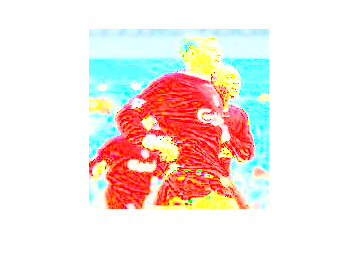

im = imread('probaD8.jpg');
r = im(:,:,1);
g = im(:,:,2);
b = im(:,:,3);

I = (double(r) + double(g) + double(b))/3;
red = double(r)./I;
gre = double(g)./I;
blu = double(b)./I;
im = cat(3, red, gre, blu);

imshow(im);

[c, f] = centerr(im, 3)

ans = 182.7503

c = 167

f = 1

%im(:,c,:) = 0;
%im(f,:,:) = 0;
[cc, ff] = centerr(im, 1)

ans = 182.7503

cc = 102

ff = 131

%im(:,cc,:) = 0;
%im(ff,:,:) = 0;

c = uint16((cc+c)/2)

c = uint16
135

f = uint16((ff+f)/2)

f = uint16
66


im(:,c,:) = 0;
im(f,:,:) = 0;

[x, y] = colCenter(im, 1, 3)

ans = 181.2137

ans = 181.2137

x = uint16
135

y = uint16
66

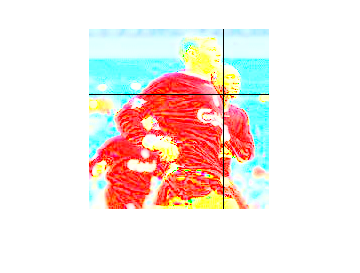


imshow(im)

%im(50,:,:) = 0;
%imshow(im);
%im(:,c,:) = 0;
%imshow(im);

cercaEquip(RGModelHist, GBModelHist, BRModelHist, RGBModelHist, imread('probaD1.jpg')) 

ans = 200.7668

ans = 200.7668

errRG = 2.3548e+03

errGB = 3.2365e+03

errBR = 2.9345e+03

errRGB = 8.2220e+03

ans = logical
   0


cercaEquip(RGModelHist, GBModelHist, BRModelHist, RGBModelHist, imread('probaD2.jpg')) 

ans = 152.4495

ans = 152.4495

errRG = 843.5874

errGB = 1.4263e+03

errBR = 1.5322e+03

errRGB = 2.2979e+03

ans = logical
   0


cercaEquip(RGModelHist, GBModelHist, BRModelHist, RGBModelHist, imread('probaD3.jpg')) 

ans = 455.3367

ans = 455.3367

errRG = 3.8295e+03

errGB = 1.6804e+03

errBR = 2.5629e+03

errRGB = 2.5644e+03

ans = logical
   0


cercaEquip(RGModelHist, GBModelHist, BRModelHist, RGBModelHist, imread('probaD4.jpg')) %PR

ans = 194.5313

ans = 194.5313

errRG = 1.6847e+03

errGB = 3.3248e+03

errBR = 2.2102e+03

errRGB = 1.0269e+04

ans = logical
   0


cercaEquip(RGModelHist, GBModelHist, BRModelHist, RGBModelHist, imread('probaD5.jpg')) %PR G->Descartaria

ans = 159.6872

ans = 159.6872

errRG = 1.7605e+03

errGB = 2.8170e+03

errBR = 1.2744e+03

errRGB = 3.6969e+03

ans = logical
   0


cercaEquip(RGModelHist, GBModelHist, BRModelHist, RGBModelHist, imread('probaD6.jpg')) 

ans = 103.6502

ans = 103.6502

errRG = 3.0764e+03

errGB = 6.1268e+03

errBR = 2.9094e+03

errRGB = 3.3764e+03

ans = logical
   0


cercaEquip(RGModelHist, GBModelHist, BRModelHist, RGBModelHist, imread('probaD7.jpg'))

ans = 352.9793

ans = 352.9793

errRG = 2.4420e+03

errGB = 1.7686e+03

errBR = 2.1188e+03

errRGB = 1.5592e+03

ans = logical
   0


cercaEquip(RGModelHist, GBModelHist, BRModelHist, RGBModelHist, imread('probaD8.jpg'))

ans = 182.7503

ans = 182.7503

errRG = 3.1583e+03

errGB = 1.3726e+03

errBR = 2.0212e+03

errRGB = 1.2373e+03

ans = logical
   0



cercaEquip(RGModelHist, GBModelHist, BRModelHist, RGBModelHist, imread('probaB1.jpg'))

ans = 315.1171

ans = 315.1171

errRG = 1.5671e+03

errGB = 1.1289e+03

errBR = 1.2478e+03

errRGB = 699.7479

ans = logical
   0


cercaEquip(RGModelHist, GBModelHist, BRModelHist, RGBModelHist, imread('probaB2.jpg')) % 

ans = 419.4766

ans = 419.4766

errRG = 2.1389e+03

errGB = 1.2252e+03

errBR = 3.0530e+03

errRGB = 1.4852e+03

ans = logical
   0


cercaEquip(RGModelHist, GBModelHist, BRModelHist, RGBModelHist, imread('probaB3.jpg')) %

ans = 172.8524

ans = 172.8524

errRG = 1.2832e+03

errGB = 2.5396e+03

errBR = 1.5523e+03

errRGB = 4.4790e+03

ans = logical
   0


cercaEquip(RGModelHist, GBModelHist, BRModelHist, RGBModelHist, imread('probaB4.jpg')) %

ans = 310.9577

ans = 310.9577

errRG = 1.4919e+03

errGB = 1.9159e+03

errBR = 2.6076e+03

errRGB = 918.4528

ans = logical
   0


cercaEquip(RGModelHist, GBModelHist, BRModelHist, RGBModelHist, imread('probaB5.jpg')) %

ans = 404.0151

ans = 404.0151

errRG = 2.5336e+03

errGB = 1.8096e+03

errBR = 1.3475e+03

errRGB = 2.4423e+03

ans = logical
   0


cercaEquip(RGModelHist, GBModelHist, BRModelHist, RGBModelHist, imread('probaB6.jpg'))

ans = NaN

ans = NaN

errRG = 1.0916e+03

errGB = 917.8764

errBR = 4.5500e+03

errRGB = 957.3879

ans = logical
   0


function [c, f] = centerr(im, d)

    [x,y] = size(im(:,:,1));
    res = zeros(1,y);
    sum(im(:,1,2))
    max = 0;
    for i = [1:y]
        res(1, i) = nansum(im(:,i,d));
        if (res(1,i) > max)
            c = i;
            max = res(1, i);
        end
    end
    max = 0;
    res = zeros(1,x);
    for i = [1:x]
        res(1, i) = nansum(im(i,:,d));
        if (res(1,i) > max)
            f = i;
            max = res(1, i);
        end
    end
end

function [c, f] = colCenter(im, d1, d2)

    [c, f] = centerr(im, d1);
    [cc, ff] = centerr(im, d2);
    
    c = uint16((cc+c)/2);
    f = uint16((ff+f)/2);

end

function [rHist, gHist, bHist, oHist] = getHists(im, tam)

    r = im(:,:,1);
    g = im(:,:,2);
    b = im(:,:,3);
    
    I = (double(r) + double(g) + double(b))/3;
    red = double(r)./I;
    gre = double(g)./I;
    blu = double(b)./I;
    
    im = cat(4, red, gre, blu, blu);
    
    [c, f] = colCenter(im, 1, 3)
    %tam = 75;
    aux = im(:,:,1);
    
    im(:,:,4) = uint8(normalize(im(:,:,2).*im(:,:,3).*aux, 'range')*255); 
    im(:,:,2) = uint8(normalize(im(:,:,2).*im(:,:,1), 'range')*255); 
    im(:,:,1) = uint8(normalize(im(:,:,1), 'range')*255);
    im(:,:,3) = uint8(normalize(im(:,:,3).*aux, 'range')*255);
    
    
    rHist = colorHistogram(f-tam, f+tam, c-tam, c+tam, 1, im);
    gHist = colorHistogram(f-tam, f+tam, c-tam, c+tam, 2, im);
    bHist = colorHistogram(f-tam, f+tam, c-tam, c+tam, 3, im);
    oHist = colorHistogram(f-tam, f+tam, c-tam, c+tam, 4, im);

end

function model = colorHistogram(xini, xfin, yini, yfin, color, im)
    model = zeros(1, 33);
    for i = [yini:yfin]
        for j = [xini:xfin]
            model(1, uint8(im(j, i, color)/8)+1) = model(1, uint8(im(j, i, color)/8)+1) + 1;
        end
    end
    %bar(model);
end

function D = distChiSq( X, Y )

    m = size(X,1);  
    n = size(Y,1);
    mOnes = ones(1,m); 
    D = zeros(m,n);
    
    for i=1:n
      yi = Y(i,:);  
      yiRep = yi( mOnes, : );
      s = yiRep + X;    
      d = yiRep - X;
      D(:,i) = sum( d.^2 ./ (s+eps), 2 );
    end
    D = D/2;
end

function result = cercaEquip(RGModelHist, GBModelHist, BRModelHist, RGBModelHist,im)
    
    [x, y] = size(im(:,:,1)); 
    r = im(:,:,1);
    g = im(:,:,2);
    b = im(:,:,3);
    
    I = (double(r) + double(g) + double(b))/3;
    red = double(r)./I;
    gre = double(g)./I;
    blu = double(b)./I;
    
    im = cat(4, red, gre, blu, blu);
    [c, f] = colCenter(im, 1, 3);
    
    result = false;
    tam = 75;
    fma = f+tam;
    fmi = f-tam;
    cmi = c-tam;
    cma = c+tam;
    if((f+tam)> x)
        fma = x;
        fmi = x-(tam*2);
        if(fmi < 1) 
            fmi = 1;
        end
    elseif((f-tam) < 1)
        fmi = 1;
        fma = 1+(tam*2);
        if(fma > x) 
            fma = x;
        end
    end
    
    if((c+tam)> y)
        cma = y;
        cmi = y-(tam*2);
        if(cmi < 1) 
            cmi = 1;
        end
    elseif((c-tam) < 1)
        cmi = 1;
        cma = 1+(tam*2);
        if(cma > y) 
            cma = y;
        end
    end
    
    aux = im(:,:,1);
    im(:,:,4) = uint8(normalize(im(:,:,2).*im(:,:,3).*aux, 'range')*255); 
    im(:,:,2) = uint8(normalize(im(:,:,2).*im(:,:,1), 'range')*255); 
    im(:,:,1) = uint8(normalize(im(:,:,1), 'range')*255);
    im(:,:,3) = uint8(normalize(im(:,:,3), 'range')*255);
    
    RGImgeHist = colorHistogram(fmi, fma, cmi, cma, 1, im);
    GBImgeHist = colorHistogram(fmi, fma, cmi, cma, 2, im);
    BRImgeHist = colorHistogram(fmi, fma, cmi, cma, 3, im);
    RGBImgeHist = colorHistogram(fmi, fma, cmi, cma, 4, im);
            
    errRG = distChiSq(RGImgeHist, RGModelHist);
    errGB = distChiSq(GBImgeHist, GBModelHist);
    errBR = distChiSq(BRImgeHist, BRModelHist);
    errRGB = distChiSq(RGBImgeHist, RGBModelHist);
    
    errRG
    errGB
    errBR
    errRGB
    
    if ((errRG+errBR) < 1000 && errGB < 500)
        %if (errGB < 800)
            result = true;
        %end
    elseif (errGB < 300)
        result = true;
    end
    %elseif ((errRG+errBR) < 1800)
    %    if (errGB < gg)
    %        result = true;
    %    end
    %end
    
end